# Ampliación de Métodos Numéricos.

# Examen de MATLAB. 

### Apellido: Gil Álamo

### **Nombre: Ángel Amando**

### **DNI: 21067743L**

**Entregad: ficheros tipo     .m .mlx .pdf**

### Ejercicio 

Calcular la recta de mínimos cuadrados que aproxime los siguientes puntos, utilizando la factorización QR reducida calculada con el algoritmo de Householder:

(0,1), (1,.3), (2.1,. 25) (3, 0.1)

A=[0,1;1,0.3;2.1,0.25;3,0.1];
[Q,R] = QRHouseholder(A)

Q =     1.0000         0         0         0
         0   -0.7442   -0.0628    0.6650
         0   -0.6202    0.4347   -0.6530
         0   -0.2481   -0.8984   -0.3625


R =          0    1.0000
   -2.7908   -0.4031
   -1.8450    0.0000
   -1.7938    0.0000


Agrande=[ones(4,1),A(:,2)];
[n,m] = size(A);
C1 = ones(n,1);
X = A(:,1);
Y = A(:,2);
for i = 1:n
    X2(i) = X(i)^2;
    X3(i) = X(i)^3;
end

A = [C1, X, X2', X3']

A =     1.0000         0         0         0
    1.0000    1.0000    1.0000    1.0000
    1.0000    2.1000    4.4100    9.2610
    1.0000    3.0000    9.0000   27.0000


Api = (A' * A)\A';
xsol = Api * Y

xsol =     1.0000
   -1.2723
    0.6964
   -0.1241


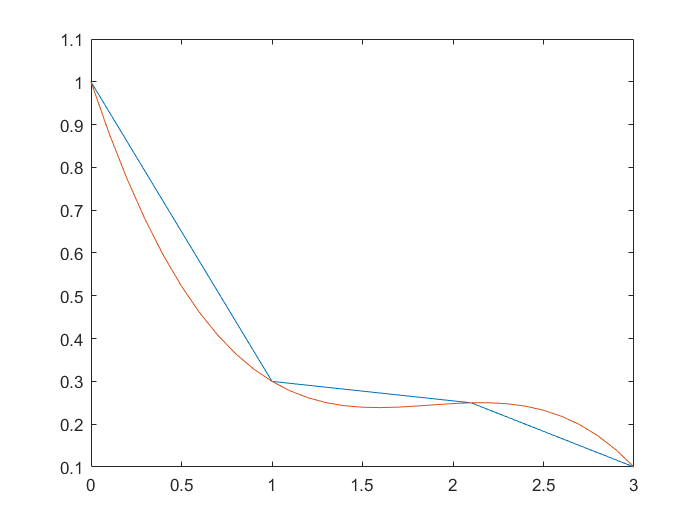

plot(X,Y)
hold on

for i = 1:4
    p(i) = xsol(4-i+1);
end

plot([0:0.1:3], polyval(p,[0:0.1:3]))
hold off

### Apéndice. Funciones auxiliares

#### 1. Factorización QR mediante proyección de Householder

function [Q,R] = QRHouseholder(A)
    [n,m]=size(A);
    Q=eye(n);
    R=A;
    for i =1:m
        v=R(i:n,i);
        v(1)=v(1)+(sign(v(1))*norm(v)); 
        F = eye(n-i+1,n-i+1)-2*(v*v')/(norm(v)^2);
        Qtemp=[eye(i-1),zeros(i-1,n-i+1);zeros(n-i+1,i-1),F];
        R=Qtemp*R;
        Q=Q*Qtemp';
    end
end